# Model of a speed control

Speed control is used in many application of mechatronic systems e. g. for robots. In  this exercise a model of a speed control system is given. This model must be  implemented using Matlab/Simulink. 

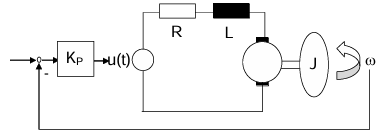

The equations are:

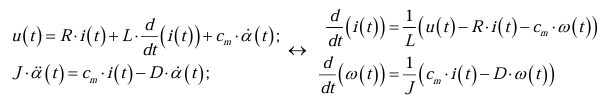

The voltage   u t is the input of the system,   M t  the output. The system will be  controlled by a proportional-controller or another controller you want to try. The  parameters are:  L = 0.23e-3 [H];   cm = 23.4e-3 [Nm/A];  R = 2.4[Ohm];  J = 0.23e-6[Nm^2];  D = 0.4191e-5 [N*sec/m];

clear; clf; clc;

## Parameters

p.L = 0.23e-3;      %[V/A*sec]
p.cm = 23.4e-3;     %[Nm/A]
p.R = 2.4;          %[Ohm]
p.J = 0.23e-6;      %[N*m^2]
p.D = 0.4191e-5;    %[Nm/rad*sec]

p.t0 = 0;           %[s] start simulation time
p.tend = 0.01;      %[s] stop simulation time

LoopController = tf(1);

## a) Open loop simulation of the motor

Build up a simulation model of the dc-motor (open-loop) and test it!

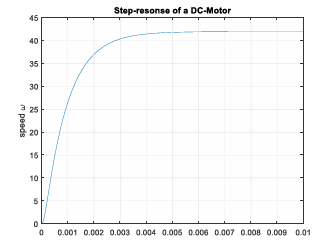

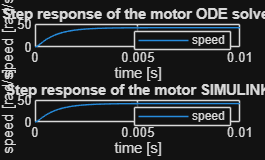

p.u = 1;    %step response to 1V power supply

[t,y] = ode45(@motorDgl,[p.t0,p.tend],[0,0],[],p);      %ODE solver
outOpenLoop = sim('exercise4_SIM');                     %SIMULINK simulation

figure()
subplot(2,1,1)      
plot(t,y(:,2))      % Plot of the simulation made with ODE solver
title("Step response of the motor ODE solver");
legend("speed")
grid on; xlabel("time [s]"); ylabel("speed [rad/s]");

subplot(2,1,2)      % Plot of the simulation made with simulink simulation
plot(outOpenLoop.openLoop.time,outOpenLoop.openLoop.signals(2).values)
title("Step response of the motor SIMULINK");
legend("speed")
grid on; xlabel("time [s]"); ylabel("speed [rad/s]");

## b) improve control 

Change the parameters of the controller to get a good control behavior! 

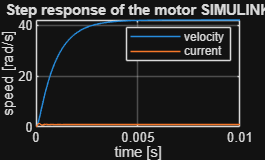

SSsys = linearize('exercise4_SIM', getlinio('exercise4_SIM')); %state space rappresentation of the simulink model
Gsys = tf(SSsys);       % Conversion to transfer function

% ---> sisotool(G)
% ---> save Controller

load LoopController.mat

outOpenLoop = sim('exercise4_SIM');

figure()
plot(outOpenLoop.closeLoop.time,outOpenLoop.closeLoop.signals(2).values,...
    outOpenLoop.closeLoop.time,outOpenLoop.closeLoop.signals(1).values)
title("Step response of the motor SIMULINK");
legend("velocity","current")
grid on; xlabel("time [s]"); ylabel("speed [rad/s]");

## c) different solver test

Try different solvers (use additionally solvers for stiff systems) and compare the  results! Plot the simulated motor-current, calculated with different solver in the  same plot!

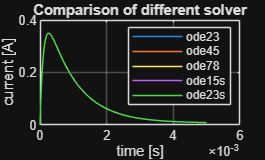

% Solving with different ode solver
[t1,y1] = ode23(@motorDgl,[p.t0,0.005],[0,0],[],p);
[t2,y2] = ode45(@motorDgl,[p.t0,0.005],[0,0],[],p);
[t3,y3] = ode78(@motorDgl,[p.t0,0.005],[0,0],[],p);
[t4,y4] = ode15s(@motorDgl,[p.t0,0.005],[0,0],[],p);
[t5,y5] = ode23s(@motorDgl,[p.t0,0.005],[0,0],[],p);

figure()
plot(t1,y1(:,1),t2,y2(:,1),t3,y3(:,1),t4,y4(:,1),t5,y5(:,1));   % Plot all the results
title("Comparison of different solver")
legend("ode23","ode45","ode78","ode15s","ode23s");
grid on; xlabel("time [s]"); ylabel("current [A]");

## Differential equation

function dz = motorDgl(t,z,p)
    i = z(1);
    w = z(2);

    di = 1/p.L * (p.u - i*p.R - p.cm*w);
    dw = 1/p.J * (i*p.cm - w*p.D);

    dz = [di; dw];  % Return the derivatives as a column vector
end

# Ottenere la funzione di trasferimendo dal modello simulink

Per ottenere in prima battuta in sistema nella forma dello spazio degli stati bisogna inserire all'ingresso del sistema l'elemento TAsto destro sul segnale > Linear analysis point > Input Perturbation e l'elemento TAsto destro sul segnale > Linear analysis point > Output measurement.

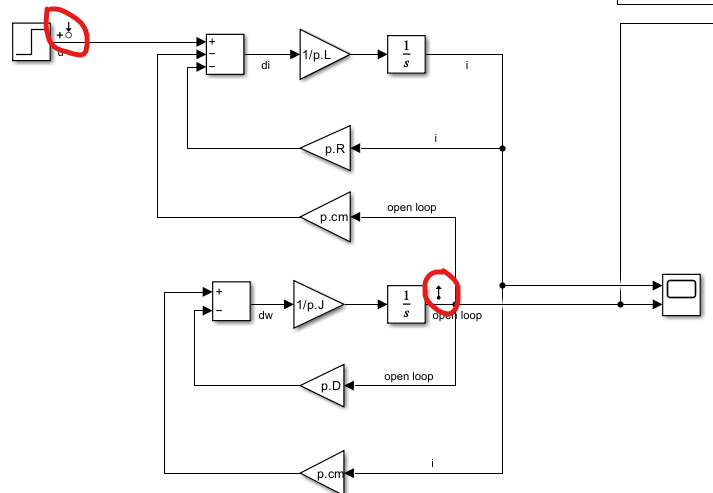

successivamente si utilizza il comando:

sys = linearize('exercise4_SIM', getlinio('exercise4_SIM')) %state space rappresentation of the simulink model


sys =
 
  A = 
                Integrator2  Integrator3
   Integrator2   -1.043e+04       -101.7
   Integrator3    1.017e+05       -18.22
 
  B = 
                Step1/u
   Integrator2     4348
   Integrator3        0
 
  C = 
              Integrator2  Integrator3
   open loop            0            1
 
  D = 
              Step1/u
   open loop        0
 
Continuous-time state-space model.


Per convertire da spazio degli stati in funzione di trasferimento si usa il comando:

G = tf(sys)


G =
 
  From input "Step1/u" to output "open loop":
           4.423e08
  ---------------------------
  s^2 + 1.045e04 s + 1.054e07
 
Continuous-time transfer function.


Infine se si vuole effettuare il tuning dei parametri per un controllore per il sistema reatroazionato:

% ---> sisotool(G)

Export the controller created with the tool box and use the command save to save the variable. To load the Variable use the load command

% ---> save Controller
load Controller.mat